clc; clear all; close all;
run('variableLoader.m')
%INPUTS
sim('inputs.slx');
load('sine_sweep.mat')
sine = squeeze(sine_sweep.Data);
input = timetable(sine,'SampleRate',50);

# Elevator input - short period mode(5secs)

paramStruct.StopTime = "5";

## elevator to pitch rate

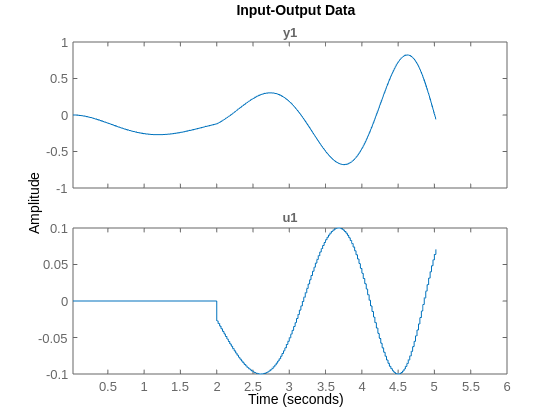

out = sim('el_pr',paramStruct);
u = out.elevator;
y = squeeze(out.pitch_rate);
data = iddata(y,u,0.02);
plot(data)

sys_el_pr= tfest(data, 3, 2)

sys_el_pr =
  From input "u1" to output "y1":
    -11.73 s^2 - 46.59 s - 22.67
  ---------------------------------
  s^3 + 1.964 s^2 + 16.29 s + 9.977
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 83.33%                   
FPE: 0.003642, MSE: 0.00339                      
 
Model Properties


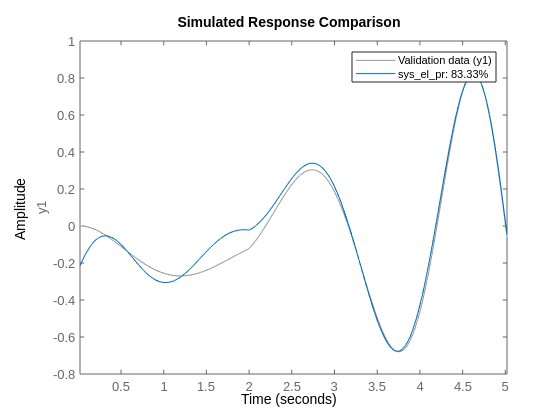

compare(data,sys_el_pr)

## elevator to aoa

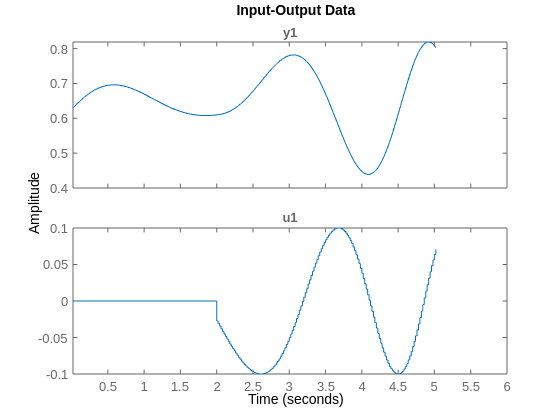

out = sim('el_a',paramStruct);
u = out.elevator;
y = squeeze(out.aoa);
data = iddata(y,u,0.02);
plot(data)

sys_el_a= tfest(data, 4, 1)

sys_el_a =
  From input "u1" to output "y1":
                   -30.97 s + 76.44
  --------------------------------------------------
  s^4 + 0.6931 s^3 + 17.77 s^2 + 9.315 s + 3.932e-11
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 1
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 19.48%                   
FPE: 0.005887, MSE: 0.005435                     
 
Model Properties


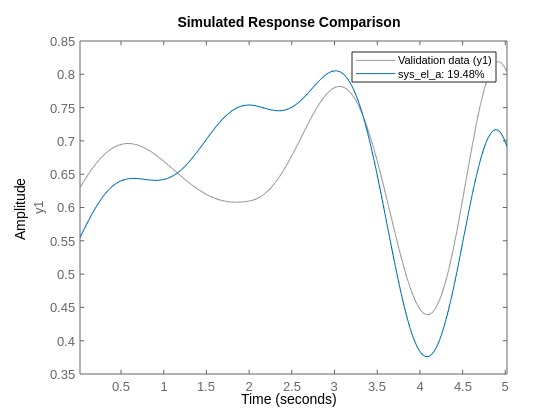

compare(data,sys_el_a)

## elevator to gamma

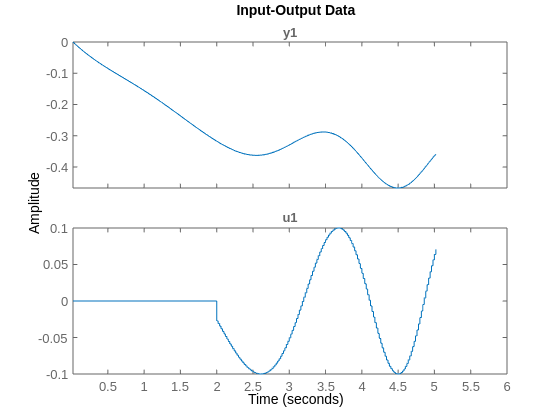

out = sim('el_g',paramStruct);
u = out.elevator;
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_el_g= tfest(data, 3, 2)

sys_el_g =
  From input "u1" to output "y1":
     1.541 s^2 - 6.402 s + 8.079
  ----------------------------------
  s^3 + 1.724 s^2 + 0.3579 s + 0.617
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 90.85%                   
FPE: 0.0001334, MSE: 0.0001242                   
 
Model Properties


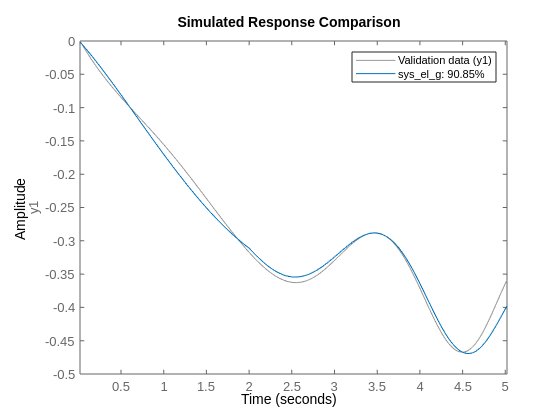

compare(data,sys_el_g)

# Elevator input - phugoid mode(20secs)

paramStruct.StopTime = "20";

## elevator to velocity

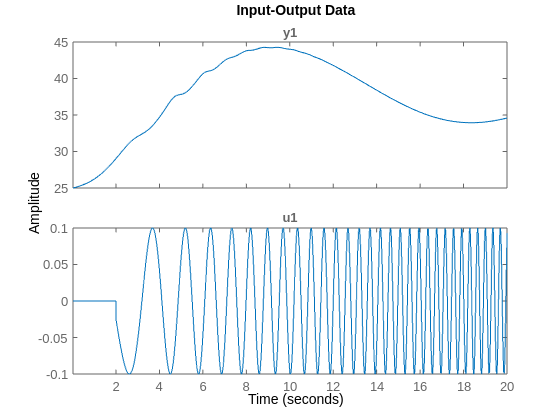

out = sim('el_v',paramStruct);
u = out.elevator;
y = squeeze(out.velocity);
data = iddata(y,u,0.02);
plot(data)

sys_el_v= tfest(data, 3, 2)

sys_el_v =
  From input "u1" to output "y1":
        -5.266 s^2 + 24.32 s + 16.7
  ---------------------------------------
  s^3 + 0.1084 s^2 + 0.1116 s + 1.029e-11
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 96.71%                   
FPE: 0.03122, MSE: 0.03067                       
 
Model Properties


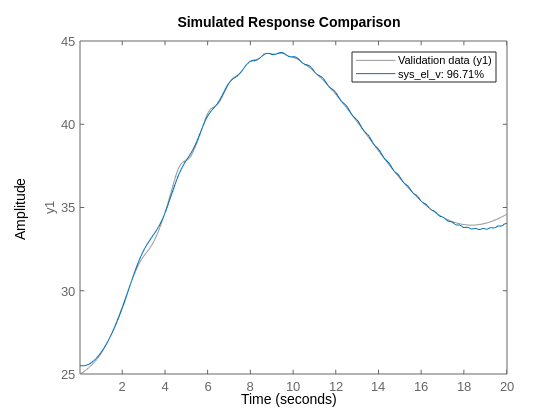

compare(data,sys_el_v)

## elevator to height

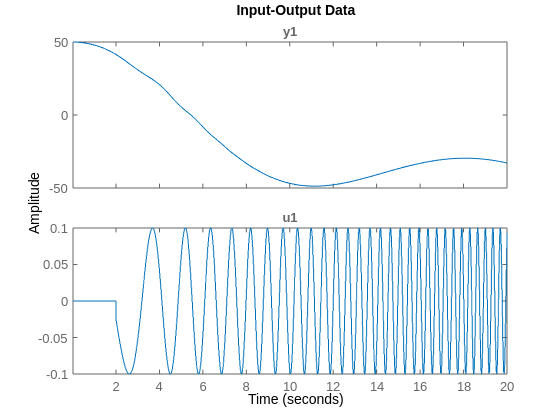

out = sim('el_h',paramStruct);
u = out.elevator;
y = squeeze(out.height);
data = iddata(y,u,0.02);
plot(data)

sys_el_h= tfest(data, 4, 2)

sys_el_h =
  From input "u1" to output "y1":
               227.2 s^2 + 136.7 s - 4.879
  -----------------------------------------------------
  s^4 + 0.4652 s^3 + 0.1841 s^2 + 0.03608 s + 0.0007803
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 4   Number of zeros: 2
   Number of free coefficients: 7
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 92.43%                   
FPE: 6.004, MSE: 5.874                           
 
Model Properties


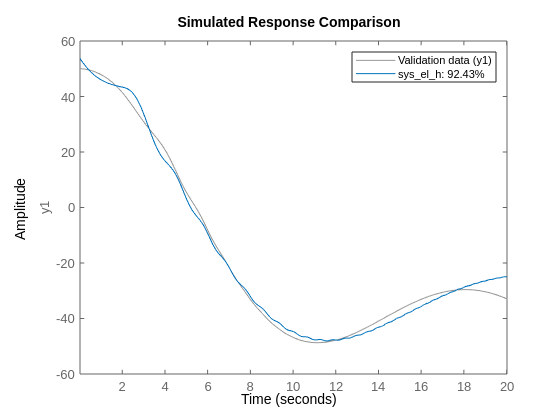

compare(data,sys_el_h)

## elevator to gamma

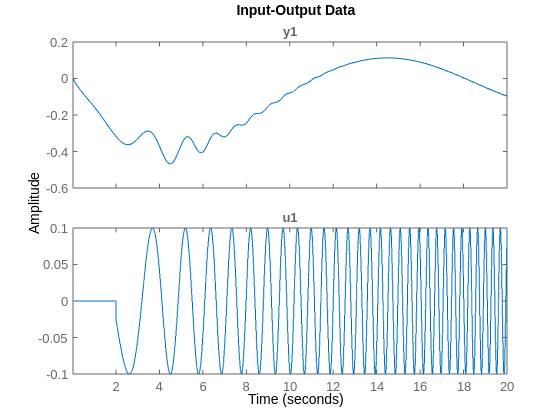

out = sim('el_g',paramStruct);
u = out.elevator;
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_el_g= tfest(data, 3, 2)

sys_el_g =
  From input "u1" to output "y1":
     -0.0338 s^2 - 3.496 s + 0.06017
  -------------------------------------
  s^3 + 0.6692 s^2 + 0.2845 s + 0.07898
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 87.25%                   
FPE: 0.0005165, MSE: 0.0005073                   
 
Model Properties


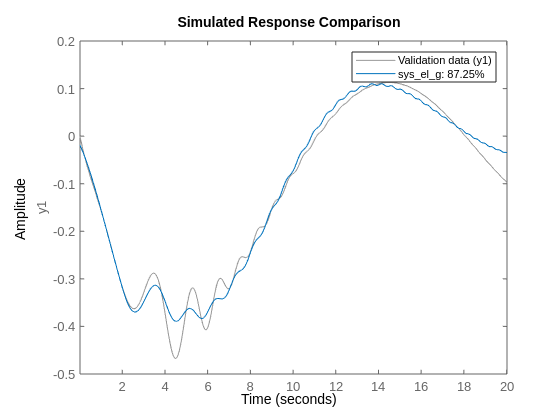

compare(data,sys_el_g)

# Throttle input - short period mode(5secs)

paramStruct.StopTime = "5";

## thrust to pitch rate

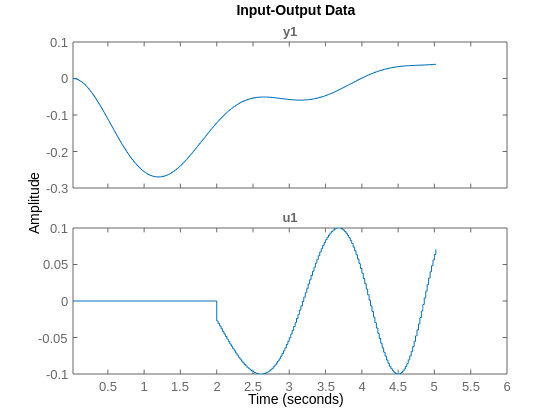

out = sim('t_pr',paramStruct);
u = out.throttle;
y = squeeze(out.pitch_rate);
data = iddata(y,u,0.02);
plot(data)

sys_t_pr= tfest(data, 2, 1)

sys_t_pr =
  From input "u1" to output "y1":
    -0.1302 s + 3.296
  ---------------------
  s^2 + 0.967 s + 1.675
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 81.84%                   
FPE: 0.0003134, MSE: 0.0002988                   
 
Model Properties


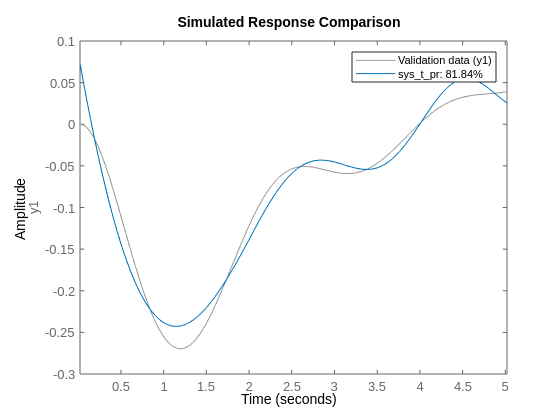

compare(data,sys_t_pr)

## thrust to aoa

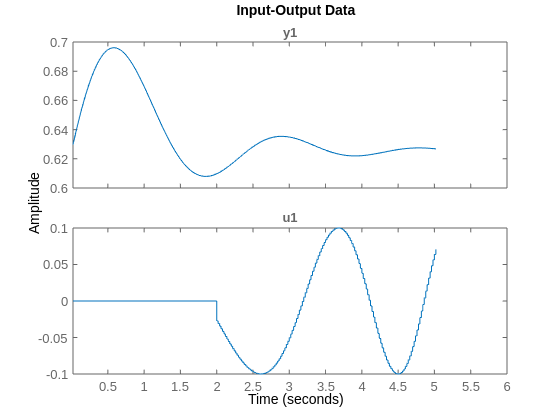

out = sim('t_a',paramStruct);
u = out.throttle;
y = squeeze(out.aoa);
data = iddata(y,u,0.02);
plot(data)

sys_t_a= tfest(data,2,2)

sys_t_a =
  From input "u1" to output "y1":
  0.01697 s^2 - 0.1755 s + 0.9798
  -------------------------------
     s^2 + 0.5582 s + 0.03816
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 2
   Number of free coefficients: 5
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: -93.31%                  
FPE: 0.002328, MSE: 0.002202                     
 
Model Properties


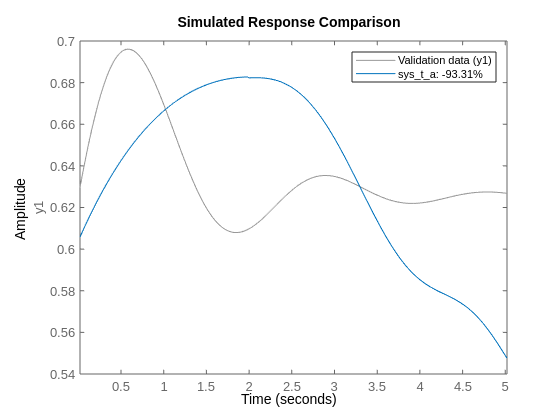

compare(data,sys_t_a)

# Throttle input - phugoid mode(20secs)

paramStruct.StopTime = "20";

## thrust to velocity

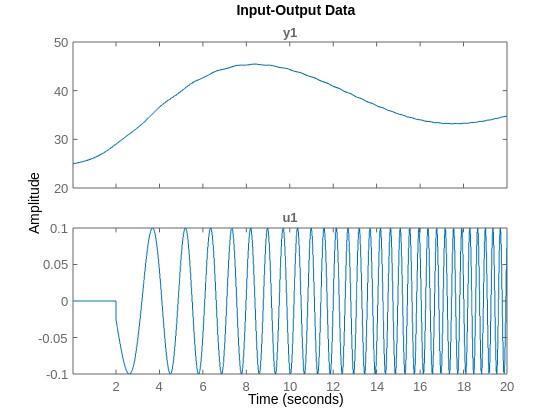

out = sim('t_v',paramStruct);
u = out.throttle;
y = squeeze(out.velocity);
data = iddata(y,u,0.02);
plot(data)

sys_t_v= tfest(data, 3, 2)

sys_t_v =
  From input "u1" to output "y1":
        -3.967 s^2 - 8.24 s + 30.25
  ---------------------------------------
  s^3 + 0.1265 s^2 + 0.1039 s + 2.966e-11
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 91.09%                   
FPE: 0.2675, MSE: 0.2627                         
 
Model Properties


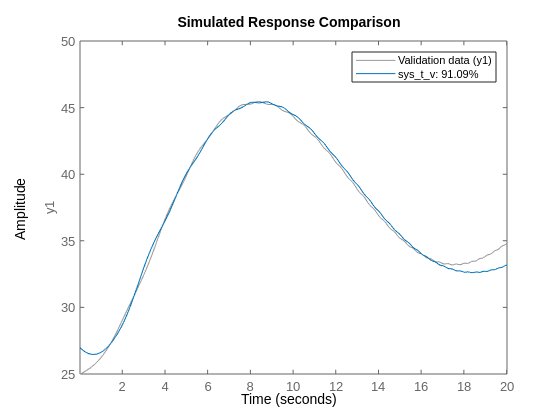

compare(data,sys_t_v)

## thrust to height

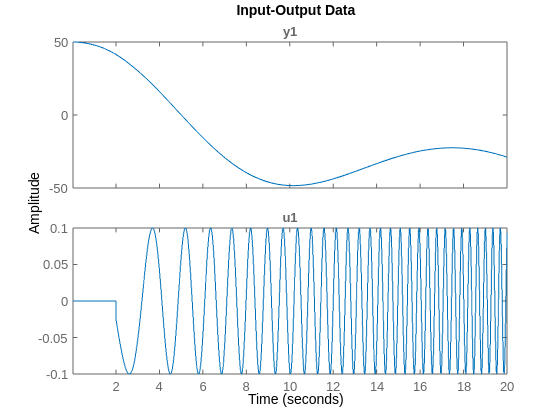

out = sim('t_h',paramStruct);
u = out.throttle;
y = squeeze(out.height);
data = iddata(y,u,0.02);
plot(data)

sys_t_h= tfest(data, 2, 0)

sys_t_h =
  From input "u1" to output "y1":
           372.2
  ------------------------
  s^2 + 0.1872 s + 0.03431
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 83.21%                   
FPE: 26.5, MSE: 26.24                            
 
Model Properties


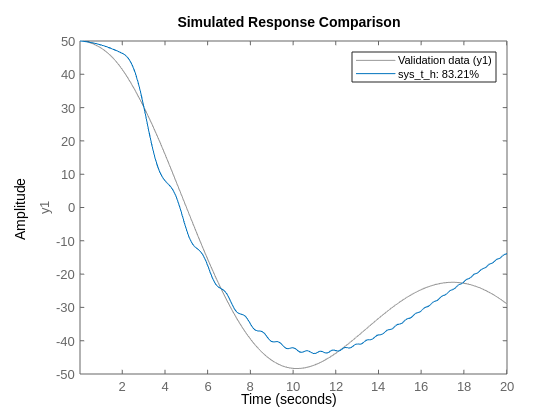

compare(data,sys_t_h)

## thrust to gamma

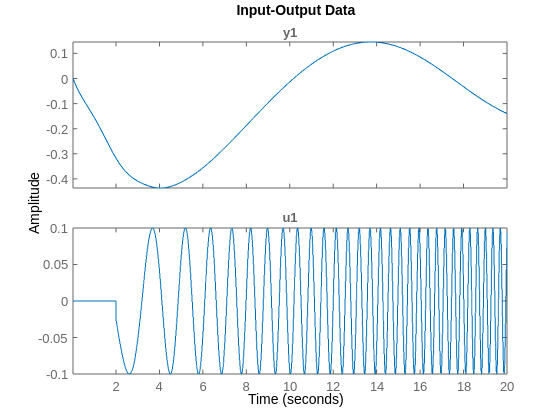

out = sim('t_g',paramStruct);
u = out.throttle;
y = squeeze(out.gamma);
data = iddata(y,u,0.02);
plot(data)

sys_t_g= tfest(data, 3, 2)

sys_t_g =
  From input "u1" to output "y1":
     0.6542 s^2 + 0.006787 s - 1.43
  -------------------------------------
  s^3 + 0.5954 s^2 + 0.2126 s + 0.05112
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 80.91%                   
FPE: 0.001411, MSE: 0.001385                     
 
Model Properties


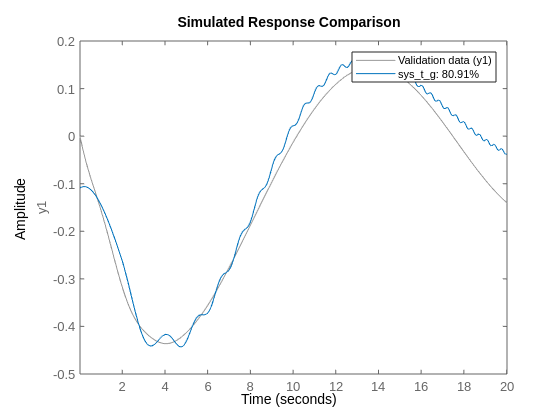

compare(data,sys_t_g)